**2. Compute the efficient frontier under the following constraints (to be considered all at once):**

- **Standard constraints**

- **The overall exposure of the companies belonging to the "Consumer Discretionary" has to be greater than 15%**

- **The overall esposure of the companies belonging to the "Industrials" has to be less than 5%**

- **The weights of the companies belonging to sectors that are composed by less than 5 companies ha so be null**

**Compute the Minimum Variance Portfolio, named Portfolio C, and the Maximum Sharpe Ratio Portfolio, named Portfolio D, of the frontier.**

clear all
close all
clc

## Load prices and sectors data

data_dir = "data/";

filename = "prices_fin.xlsx";
table_prices = readtable(data_dir + filename);
filename2 = "sectors_fin.xlsx";
table_Sec = readtable(filename2,"TextType","string");

## Transform prices to log prices

dt = table_prices(:,1).Variables;
values = table_prices(:,2:end).Variables;
nm = table_prices.Properties.VariableNames(2:end);

myPrice_dt = array2timetable(values, 'RowTimes', dt, 'VariableNames', nm);

start_dt = datetime('11/05/2021', 'InputFormat', 'dd/MM/yyyy');
end_dt   = datetime('11/05/2023', 'InputFormat', 'dd/MM/yyyy');

rng = timerange(start_dt, end_dt, 'Closed');
subsample = myPrice_dt(rng, :);
prices_val = subsample.Variables;
LogRet = tick2ret(prices_val, 'Method', 'continuous');
N_asset = size(LogRet,2);

## Variance and Mean

V = cov(LogRet);
var_ = var(LogRet);
ExpRet = mean(LogRet);

## Sectors

% consumer discretionary, find the indices
consumer_Discretionary = (table_Sec.Sector == 'Consumer Discretionary');
% industry
industry = (table_Sec.Sector == 'Industry');
% find sectors with less than 5 companies
groupCounts_Sec = groupcounts(table_Sec, "Sector");
small_sectors = groupCounts_Sec((groupCounts_Sec.GroupCount < 5),:);
toofew = (ismember(table_Sec.Sector,small_sectors.Sector));

## Creation of N random portfolio

N = 100000;
RetPtfs=zeros(1,N);
VolPtfs = zeros(1,N);
SharpePtfs = zeros(1,N);

for n = 1:N
    w = rand(1,N_asset);
    w_norm = w./sum(w);
    %calculate expected return of portfolio
    exp_ret_ptf = w_norm * ExpRet';
    exp_vol_ptf = sqrt(w_norm*V*w_norm');
    sharpe_ratio = exp_ret_ptf/exp_vol_ptf;

    RetPtfs(n) = exp_ret_ptf;
    VolPtfs(n) = exp_vol_ptf;
    SharpePtfs(n) = sharpe_ratio;
end

## Plot

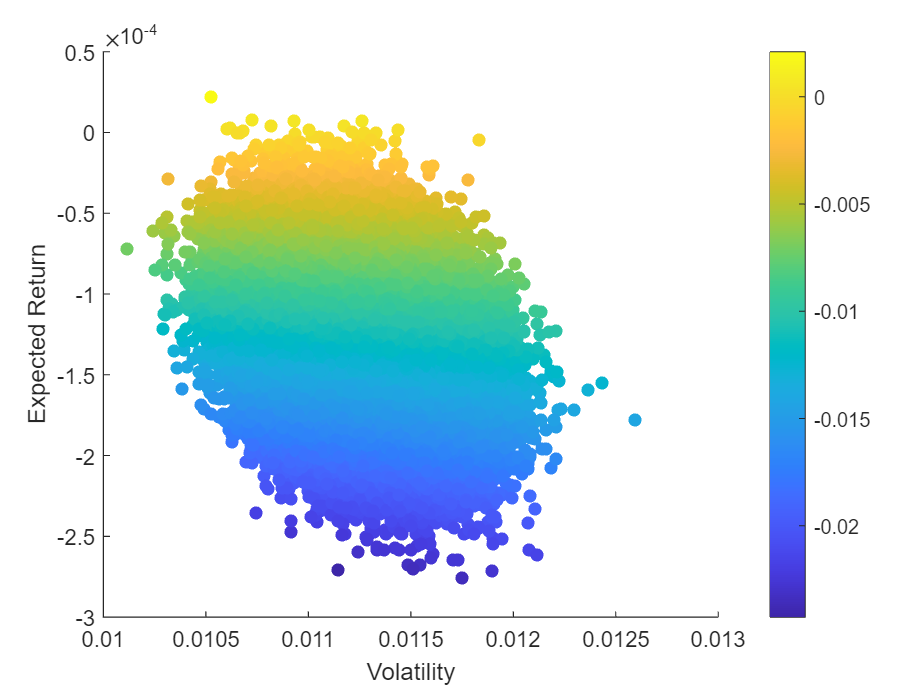

h = figure;
title('Expected Return VS Volatility')
scatter(VolPtfs, RetPtfs, [], SharpePtfs, 'filled')
colorbar
xlabel('Volatility')
ylabel('Expected Return')

## Portfolio Frontier

fun = @(x) x'*V*x;
ret_ = linspace(min(RetPtfs), max(RetPtfs), 100);

x0 = rand(N_asset, 1);
x0 = x0./sum(x0);

% Standard constraints
lb = zeros(1,N_asset);
ub = ones(1,N_asset);
FrontierVol = zeros(1,length(ret_));
FrontierRet = zeros(1,length(ret_));

% Inequality constraints
% Consumer discretionary
A_CD = -consumer_Discretionary';
b_CD = 0.15;
% industry
A_Industry = industry';
b_industry = 0.05;
% Inequality constraints
A = [A_CD; A_Industry];
b = [b_CD; b_industry];
% Less than 5 companies
A_small = eye(N_asset);
A_small = A_small(toofew,:);
b_small = zeros(sum(toofew),1);

for i = 1:length(ret_)
    r = ret_(i);
    % standard constraints
    Aeq = [ones(1,N_asset); ExpRet; A_small];
    beq = [1, r, b_small'];
    w_opt = fmincon(fun, x0, [],[], Aeq, beq, lb, ub);
    min_vol = sqrt(w_opt'*V*w_opt);

    FrontierVol(i) = min_vol;
    FrontierRet(i) = r;
end


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.


Solver

## Plot

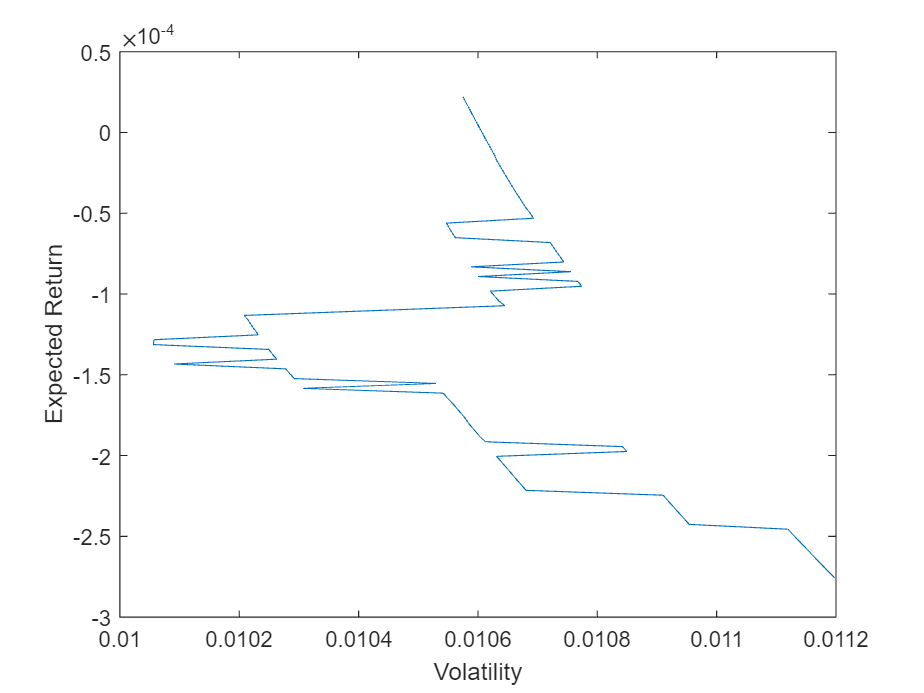

h = figure;
title('Expected Return VS Volatility')
plot(FrontierVol, FrontierRet)
xlabel('Volatility')
ylabel('Expected Return')